# CSB estiamtion for Dengue model: 

# multiple estimations to test algorithm

**Load the real data:** Itagüí, Colombia

load('Itagui.mat');

ydata = Itagui(1:40)';

D = length(ydata);
Domain = [0 D-1];
xdata = 0 : D-1;

**Create the model as a table for GSUA-CSB toolbox implementation**

First, define the model as a symbolic structure

syms  Ms(t) Me(t) Mi(t) Hs(t) He(t) Hi(t) Hr(t) Hit(t)
syms lambda beta_m mu_m theta_m mu_h beta_h theta_h...
    gamma_h

H = Hs + He + Hi + Hr;
M = Ms + Me + Mi;

ode1 = diff(Ms) == lambda - beta_m * Hi * Ms/H - mu_m * Ms;
ode2 = diff(Me) == beta_m * Hi * Ms/H - (theta_m + mu_m) * Me;
ode3 = diff(Mi) == theta_m * Me - mu_m * Mi;
ode4 = diff(Hs) == - beta_h * Mi * Hs/M + (He + Hi + Hr) * mu_h;
ode5 = diff(He) == beta_h * Mi * Hs/M - (theta_h + mu_h) * He;
ode6 = diff(Hi) == theta_h * He - (gamma_h + mu_h) * Hi;
ode7 = diff(Hr) == gamma_h * Hi - mu_h * Hr;
ode8 = diff(Hit) == theta_h * He;

odes = [ode1; ode2 ;ode3; ode4; ode5 ;ode6; ode7; ode8];
vars = [Hit Hi Me Hr Hs He Ms Mi];

opts = odeset('NonNegative',1:8);

Then, define the factor intervals with their corresponding names.

Range1 = [17 17             %Hit0
          17 17             %Hi    
          0	100             %Me
          0 100             %Hr
          50000	250000      %Hs
          0	1000            %He
          0	120000          %Ms
          0	100             %Mi
         ];
     
Range2 = [0	4
          0	4
          0.4	1.8
          0	42694
          0.0004 0.0004
          0.01 0.6
          0.7	1.75
          0.58	0.88
        ];     

Range = [Range1; Range2];

ParNames = {'\lambda'; '\beta_m'; '\mu_m'; '\theta_m'; '\beta_h'; '\theta_h'; '\gamma_h'};
VarNames = {'M_e(0)'; 'H_r(0)'; 'H_s(0)'; 'H_e(0)'; 'M_s(0)'; 'M_i(0)'};

FullNames = [VarNames; ParNames];

Finally, use the gsua_dpmat to create the functional table

[T,~] = gsua_dpmat(odes,vars,[0 39],'Model','output',2,'opt',opts,'Range',Range);

Introduce ranges in the following order: 


$$ans(t) = \left(\begin{array}{cccccccccccccccc} \mathrm{Hit}\left(t\right) & \mathrm{Hi}\left(t\right) & \mathrm{Me}\left(t\right) & \mathrm{Hr}\left(t\right) & \mathrm{Hs}\left(t\right) & \mathrm{He}\left(t\right) & \mathrm{Ms}\left(t\right) & \mathrm{Mi}\left(t\right) & \beta_{h} & \beta_{m} & \gamma_{h} & \lambda & \mu_{h} & \mu_{m} & \theta_{h} & \theta_{m} \end{array}\right)$$

T.Row = ["M_e(0)"; 'H_r(0)'; 'H_s(0)'; 'H_e(0)'; 'M_s(0)'; 'M_i(0)';...
         '\beta_h';'\beta_m'; '\gamma_h';'\Lambda'; '\mu_m'; '\theta_h'; '\theta_m'];

Define the nominal curve as the best factor estimation

load('Results/Estimations/Best_Itagui.mat')
T.Nominal = BestParams';

**Perform the once-at-time (OAT) algorithm before CSB estimation**

T_oat = gsua_oatr(T);

Expansion-reduction Method OAT is being launched
------------------------------------
Calculus of \theta_m Starting
Range for \theta_m Done!
Initial range of \theta_m(13)--> 0.58        0.88
Actual range --> 0.3728     0.85245
Calculus of \theta_h Starting
Range for \theta_h Done!
Initial range of \theta_h(12)--> 0.7        1.75
Actual range --> 0.87153      1.7231
Calculus of \mu_m Starting
Range for \mu_m Done!
Initial range of \mu_m(11)--> 0.01         0.6
Actual range --> 0.50719     0.58473
Calculus of \Lambda Starting
Range for \Lambda Done!
Initial range of \Lambda(10)--> 0  42694
Actual range --> 0.45555      2.1666
Calculus of \gamma_h Starting
Range for \gamma_h Done!
Initial range of \gamma_h(9)--> 0.4         1.8
Actual range --> 0.74573      1.0214
Calculus of \beta_m Starting
Range for \beta_m Done!
Initial range of \beta_m(8)--> 0  4
Actual range --> 1.0409      1.3919
Calculus of \beta_h Starting
Range for \beta_h Done!
Initial range of \beta_h(7)--> 0  4
Actual range -

**1. CSB estimation: protecting the nominal value **

N = 5000;
Experiments = 100;
reps = 200;
Up = zeros(13, Experiments);
Low = zeros(13, Experiments);
In = zeros(1, Experiments);

parfor i = 1 : Experiments
    [ParU, ~, ~, ~,sup] = gsua_csb(T_oat, N, 'reps', reps, 'protect', true)
    Low(:, i) = ParU.Range(:, 1);
    Up(:, i) = ParU.Range(:, 2);
    In(i) = max(sup);
    Iters(i) = find(sup == max(sup))
end

save("Results/CSB/CSBRangeProtected_skewness_N_5000", "Low","Up", "In","Iters")

**1.1. CSB estimation: Uniqueness for protecting nominal value**

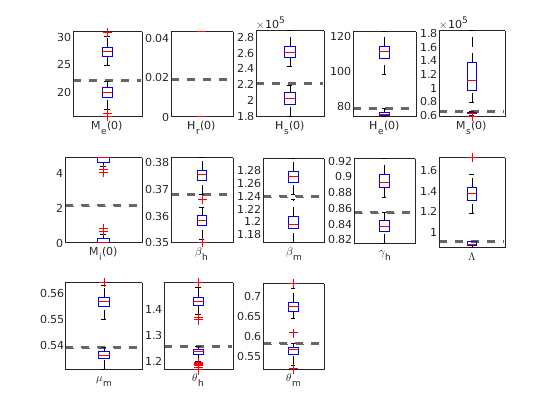

load("Results/CSB/CSBRangeProtected_skewness_N_5000")

Np = 13;
D1 = floor(sqrt(Np));%Number of subplots
D2 = D1+ceil((Np-D1^2)/D1);%Number of subplots

clf
for i=1:Np
    subplot(D1,D2,i)
    boxplot(Low(i,:))
    hold on
    boxplot(Up(i, :),'Labels',T_oat.Properties.RowNames{i})
    set(gca, 'TickLabelInterpreter', 'tex');
    ylim([min(Low(i,:)) max(Up(i,:))])
    yline(BestParams(i),'--', 'linewidth',2)
end

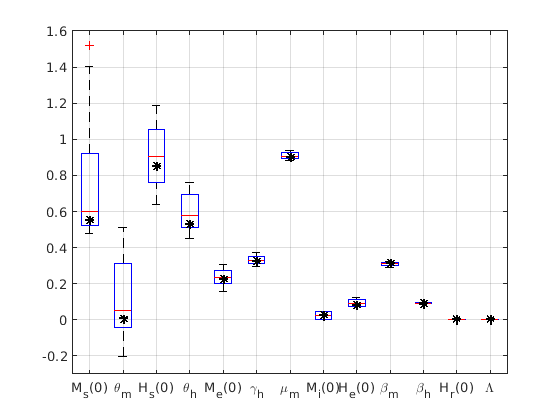

range = T.Range;
NInter = ([Low,Up] - range(:,1))./(range(:,2)-range(:,1));
Names = T.Row;
Best = (BestParams' - range(:,1))./(range(:,2)-range(:,1));
clf

TotSize = (max(NInter,[],2) - min(NInter,[],2));
[~, idx] = sort(TotSize,'descend');
NInter = NInter(idx,:);
Names = Names(idx);
Best= Best(idx);

boxplot(NInter')
hold on
plot(1:13,Best,'*', 'color', 'k', 'linewidth',2)
ylim([-0.3 1.6])
set(gca,'xticklabel',Names)
set(gca, 'TickLabelInterpreter', 'tex');
grid on

Estimate the uniqueness index

unity(Up,Low,T_oat.Range)

ans = 0.8607

**Plot the histograms for upper and lower CSB intervals estimated**

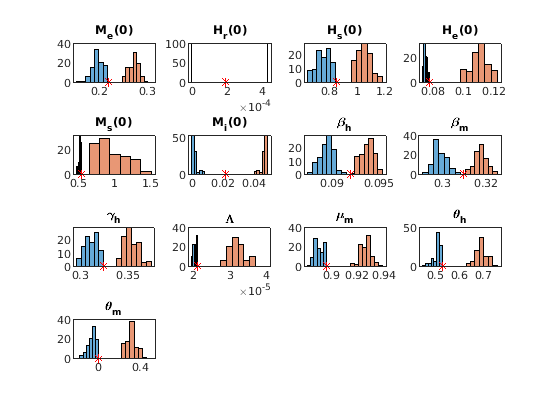

range = T.Range;
LowN = (Low - range(:,1))./(range(:,2)-range(:,1));
UpN = (Up - range(:,1))./(range(:,2)-range(:,1));
Names = T.Row;
Best = (BestParams' - range(:,1))./(range(:,2)-range(:,1));
clf

TotSize = (max(NInter,[],2) - min(NInter,[],2));
[~, idx] = sort(TotSize,'descend');
NInter = NInter(idx,:);
Names = Names(idx);
Best= Best(idx);

LowN = LowN(idx,:);
UpN = UpN(idx,:);

for i = 1:13
    subplot(4,4,i)
    histogram(LowN(i,:),'BinLimits',[min(LowN(i,:)), max(LowN(i,:))])
    hold on
    histogram(UpN(i,:),'BinLimits',[min(UpN(i,:)), max(UpN(i,:))])
    plot(Best(i), 0, 'r.','MarkerSize',16)
    title(Names(i))
end

**1.2. SA: median of multiple CSB estimations**

MedianUp = median(Up');
MedianLow = median(Low');
T.Range(:,1) = MedianLow;
T.Range(:,2) = MedianUp;
N = 10000; 
M = gsua_dmatrix(T, N, 'Method', 'Sobol');
T_sa = gsua_sa(M, T);

Progress: 7%
Estimated processing time (h:m:s): 0:1:37
Remaining time (h:m:s): 0:1:31
Elapsed time (h:m:s): 0:0:6
Estimated stop time (h:m:s): 18:12:42
Number of simulations: 75000
Progress: 14%
Estimated processing time (h:m:s): 0:1:37
Remaining time (h:m:s): 0:1:24
Elapsed time (h:m:s): 0:0:12
Estimated stop time (h:m:s): 18:12:42
Number of simulations: 75000
Progress: 20%
Estimated processing time (h:m:s): 0:1:37
Remaining time (h:m:s): 0:1:17
Elapsed time (h:m:s): 0:0:19
Estimated stop time (h:m:s): 18:12:42
Number of simulations: 75000
Progress: 27%
Estimated processing time (h:m:s): 0:1:36
Remaining time (h:m:s): 0:1:10
Elapsed time (h:m:s): 0:0:25
Estimated stop time (h:m:s): 18:12:41
Number of simulations: 75000
Progress: 34%
Estimated processing time (h:m:s): 0:1:36
Remaining time (h:m:s): 0:1:4
Elapsed time (h:m:s): 0:0:32
Estimated stop time (h:m:s): 18:12:41
Number of simulations: 75000
Progress: 40%
Estimated processing time (h:m:s): 0:1:36
Remaining time (h:m:s): 0:0:58
E

sum(T_sa.Si)/sum(abs(T_sa.Si))

ans = 1.0000

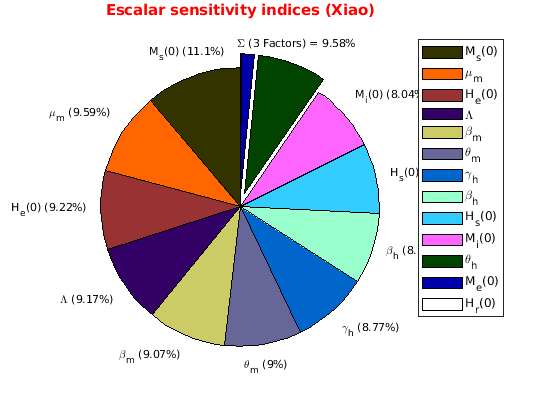

clf
gsua_plot('Pie',T_sa,T_sa.STi)

**1.3. SA: random CSB estimation**

T.Range(:,1) = Low(:,50);
T.Range(:,2) = Up(:,50);
N = 10000; 
M = gsua_dmatrix(T, N, 'Method', 'Sobol');
T_sa = gsua_sa(M, T);

Progress: 7%
Estimated processing time (h:m:s): 0:1:47
Remaining time (h:m:s): 0:1:40
Elapsed time (h:m:s): 0:0:7
Estimated stop time (h:m:s): 18:16:7
Number of simulations: 75000
Progress: 14%
Estimated processing time (h:m:s): 0:1:44
Remaining time (h:m:s): 0:1:30
Elapsed time (h:m:s): 0:0:13
Estimated stop time (h:m:s): 18:16:4
Number of simulations: 75000
Progress: 20%
Estimated processing time (h:m:s): 0:1:45
Remaining time (h:m:s): 0:1:24
Elapsed time (h:m:s): 0:0:21
Estimated stop time (h:m:s): 18:16:5
Number of simulations: 75000
Progress: 27%
Estimated processing time (h:m:s): 0:1:42
Remaining time (h:m:s): 0:1:14
Elapsed time (h:m:s): 0:0:27
Estimated stop time (h:m:s): 18:16:2
Number of simulations: 75000
Progress: 34%
Estimated processing time (h:m:s): 0:1:40
Remaining time (h:m:s): 0:1:6
Elapsed time (h:m:s): 0:0:33
Estimated stop time (h:m:s): 18:16:0
Number of simulations: 75000
Progress: 40%
Estimated processing time (h:m:s): 0:1:39
Remaining time (h:m:s): 0:0:59
Elapse

sum(T_sa.Si)/sum(abs(T_sa.Si))

ans = 1.0000

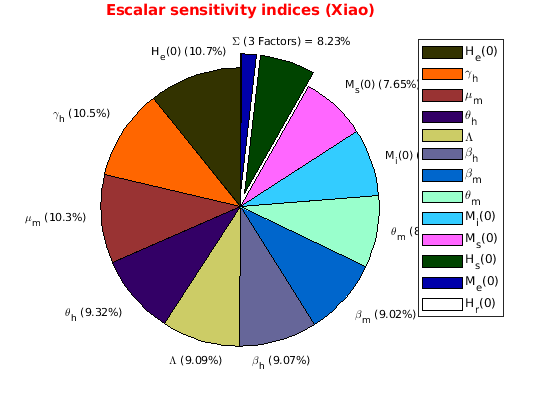

clf
gsua_plot('Pie',T_sa,T_sa.STi)

**2. CSB estimation: withou protecting the nominal value **

N = 2000;
Experiments = 100;
reps = 200;
Up = zeros(13, Experiments);
Low = zeros(13, Experiments);
In = zeros(1, Experiments);

parfor i = 1 : Experiments
    [ParU, ~, ~, ~,sup] = gsua_csb(T_oat, N, 'reps', reps, 'protect', false)
    Low(:, i) = ParU.Range(:, 1);
    Up(:, i) = ParU.Range(:, 2);
    In(i) = max(sup);
    Iters(i) = find(sup == max(sup))
end

save("Results/CSB/CSBRangeUnProtected_skewness_N_5000", "Low","Up", "In")

**2.1. CSB estimation: Uniqueness without protecting the nominal value**

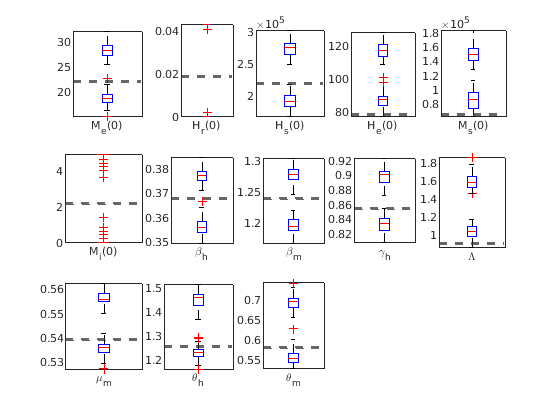

load("Results/CSB/CSBRangeUnProtected_skewness_N_5000.mat" )

Np = 13;
D1 = floor(sqrt(Np));%Number of subplots
D2 = D1+ceil((Np-D1^2)/D1);%Number of subplots

for i=1:Np
    subplot(D1,D2,i)
    boxplot(Low(i,:))
    hold on
    boxplot(Up(i, :),'Labels',T_oat.Properties.RowNames{i})
    set(gca, 'TickLabelInterpreter', 'tex');
    ylim([min(Low(i,:)) max(Up(i,:))])
    yline(BestParams(i),'--', 'linewidth',2)
end

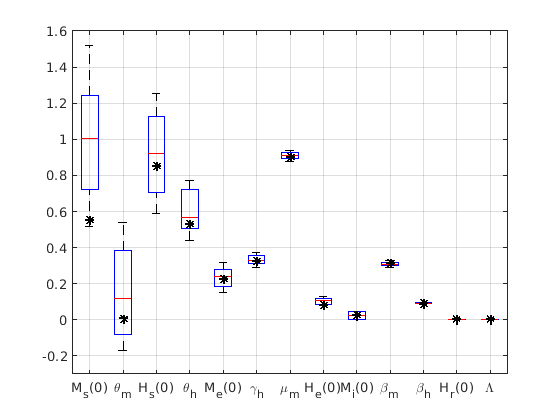

range = T.Range;
NInter = ([Low,Up] - range(:,1))./(range(:,2)-range(:,1));
Names = T.Row;
Best = (BestParams' - range(:,1))./(range(:,2)-range(:,1));
clf

TotSize = (max(NInter,[],2) - min(NInter,[],2));
[~, idx] = sort(TotSize,'descend');
NInter = NInter(idx,:);
Names = Names(idx);
Best= Best(idx);

boxplot(NInter')
hold on
plot(1:13,Best,'*', 'color', 'k', 'linewidth',2)
ylim([-0.3 1.6])
set(gca,'xticklabel',Names)
set(gca, 'TickLabelInterpreter', 'tex');
grid on

Estimate the uniqueness index

res = unity(Up,Low,T_oat.Range)

res = 0.8445

**Plot the histograms for upper and lower CSB intervals estimated**

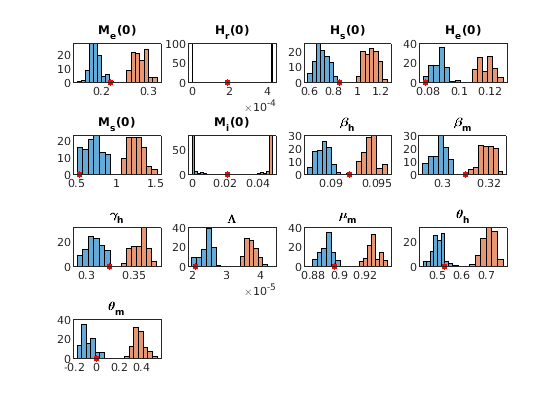

range = T.Range;
LowN = (Low - range(:,1))./(range(:,2)-range(:,1));
UpN = (Up - range(:,1))./(range(:,2)-range(:,1));
Names = T.Row;
Best = (BestParams' - range(:,1))./(range(:,2)-range(:,1));
clf

TotSize = (max(NInter,[],2) - min(NInter,[],2));
[~, idx] = sort(TotSize,'descend');
NInter = NInter(idx,:);
Names = Names(idx);
Best= Best(idx);

LowN = LowN(idx,:);
UpN = UpN(idx,:);

for i = 1:13
    subplot(4,4,i)
    histogram(LowN(i,:),'BinLimits',[min(LowN(i,:)), max(LowN(i,:))])
    hold on
    histogram(UpN(i,:),'BinLimits',[min(UpN(i,:)), max(UpN(i,:))])
    plot(Best(i), 0, 'r.','MarkerSize',16)
    title(Names(i))
end

**2.2. SA: median of multiple CSB estimations**

MedianUp = median(Up');
MedianLow = median(Low');
T.Range(:,1) = MedianLow;
T.Range(:,2) = MedianUp;

N = 10000; 
M = gsua_dmatrix(T, N, 'Method', 'Sobol');
T_sa = gsua_sa(M, T);

Progress: 7%
Estimated processing time (h:m:s): 0:1:40
Remaining time (h:m:s): 0:1:33
Elapsed time (h:m:s): 0:0:6
Estimated stop time (h:m:s): 18:25:2
Number of simulations: 75000
Progress: 14%
Estimated processing time (h:m:s): 0:1:40
Remaining time (h:m:s): 0:1:26
Elapsed time (h:m:s): 0:0:13
Estimated stop time (h:m:s): 18:25:2
Number of simulations: 75000
Progress: 20%
Estimated processing time (h:m:s): 0:1:39
Remaining time (h:m:s): 0:1:19
Elapsed time (h:m:s): 0:0:19
Estimated stop time (h:m:s): 18:25:2
Number of simulations: 75000
Progress: 27%
Estimated processing time (h:m:s): 0:1:38
Remaining time (h:m:s): 0:1:12
Elapsed time (h:m:s): 0:0:26
Estimated stop time (h:m:s): 18:25:1
Number of simulations: 75000
Progress: 34%
Estimated processing time (h:m:s): 0:1:38
Remaining time (h:m:s): 0:1:5
Elapsed time (h:m:s): 0:0:32
Estimated stop time (h:m:s): 18:25:1
Number of simulations: 75000
Progress: 40%
Estimated processing time (h:m:s): 0:1:38
Remaining time (h:m:s): 0:0:59
Elapse

sum(T_sa.Si)/sum(abs(T_sa.Si))
clf

ans = 1.0000

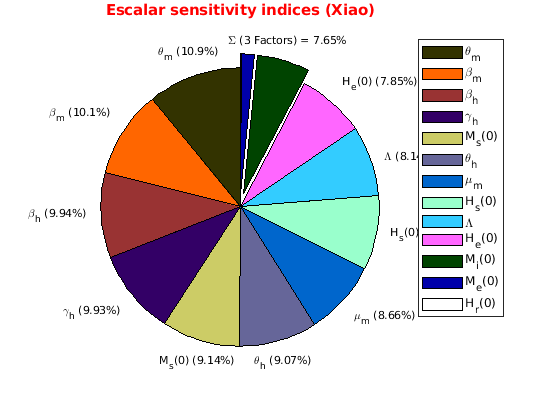

gsua_plot('Pie',T_sa,T_sa.STi)

**2.3. SA: random CSB estimation**

T.Range(:,1) = Low(:,50);
T.Range(:,2) = Up(:,50);
N = 10000; 
M = gsua_dmatrix(T, N, 'Method', 'Sobol');
T_sa = gsua_sa(M, T);

Progress: 7%
Estimated processing time (h:m:s): 0:1:41
Remaining time (h:m:s): 0:1:34
Elapsed time (h:m:s): 0:0:6
Estimated stop time (h:m:s): 18:27:42
Number of simulations: 75000
Progress: 14%
Estimated processing time (h:m:s): 0:1:39
Remaining time (h:m:s): 0:1:26
Elapsed time (h:m:s): 0:0:13
Estimated stop time (h:m:s): 18:27:41
Number of simulations: 75000
Progress: 20%
Estimated processing time (h:m:s): 0:1:38
Remaining time (h:m:s): 0:1:19
Elapsed time (h:m:s): 0:0:19
Estimated stop time (h:m:s): 18:27:40
Number of simulations: 75000
Progress: 27%
Estimated processing time (h:m:s): 0:1:38
Remaining time (h:m:s): 0:1:12
Elapsed time (h:m:s): 0:0:26
Estimated stop time (h:m:s): 18:27:39
Number of simulations: 75000
Progress: 34%
Estimated processing time (h:m:s): 0:1:39
Remaining time (h:m:s): 0:1:6
Elapsed time (h:m:s): 0:0:33
Estimated stop time (h:m:s): 18:27:40
Number of simulations: 75000
Progress: 40%
Estimated processing time (h:m:s): 0:1:38
Remaining time (h:m:s): 0:0:59
E

sum(T_sa.Si)/sum(abs(T_sa.Si))

ans = 0.9999

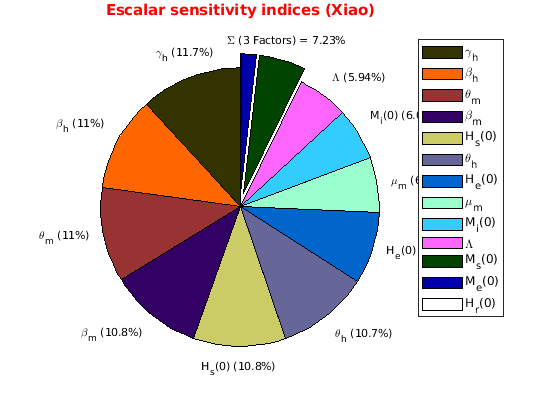

clf
gsua_plot('Pie',T_sa,T_sa.STi)

# **Performance with multiple number of samples (140, 500, 1000, 2000)**

N = [140, 500, 1000, 2000];
Experiments = 100;
reps = 200;

for j = 1 : length(N)
    Up = zeros(13, Experiments);
    Low = zeros(13, Experiments);
    In = zeros(1, Experiments);
    err = zeros(1, Experiments);
    Iters = zeros(1, Experiments);
    parfor i = 1 : Experiments
        [ParU, ~, ~, ~,sup, E] = gsua_csb(T_oat, N(j), 'reps', reps, 'protect', true);
        Low(:, i) = ParU.Range(:, 1);
        Up(:, i) = ParU.Range(:, 2);
        In(i) = max(sup);
        Iters(i) = find(sup == max(sup), 1, 'last' );
        err(i) = max(abs(E));
    end
    save("Results/CSB/CSBRangeProtected_skewness_N_" + num2str(N(j)), "Low","Up", "In", "Iters","err")
end